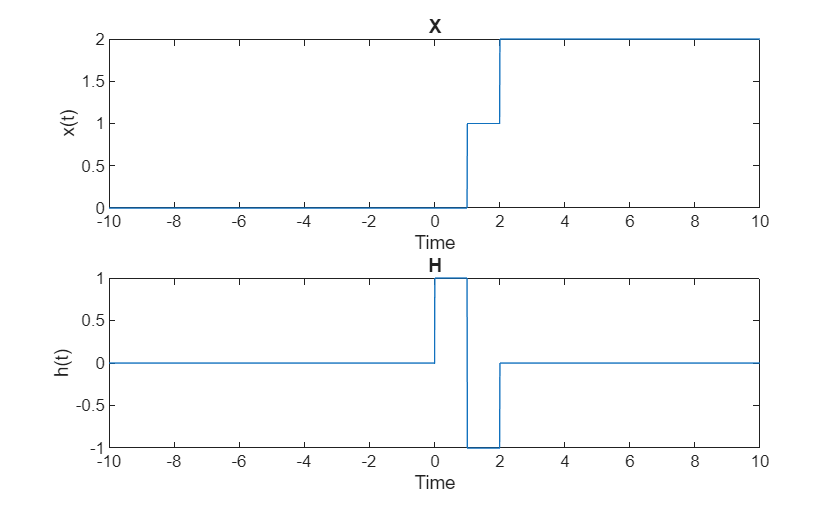

%Define time vector:
dt = 0.01;           
t = -10:dt:10;

a = double(t-1>0);
b = double(t-2>0);
c = double(t>0);
x = a+b;
h = c-2*a + b;
figure;
subplot(2,1,1);
plot(t,x);
xlabel('Time');
ylabel('x(t)');
title('X');
subplot(2,1,2);
plot(t,h);
xlabel('Time');
ylabel('h(t)');
title('H');

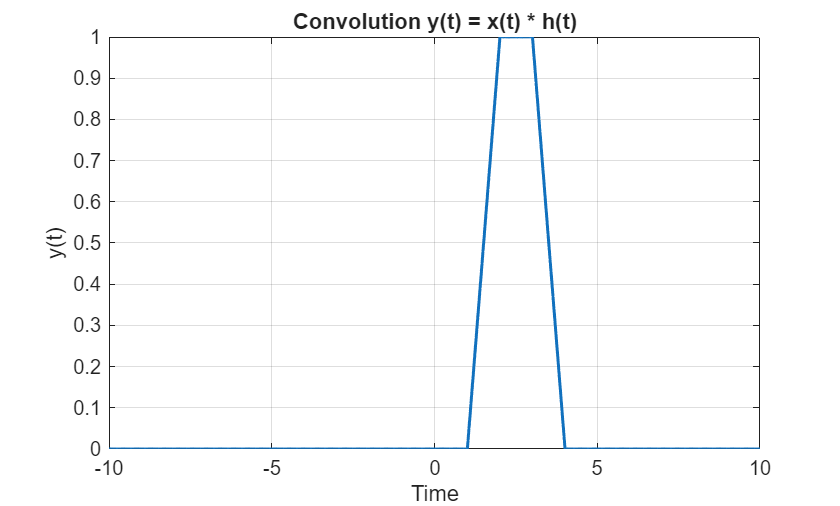

x_flipped = fliplr(x);
% Pad h:
L_x = length(x_flipped);
L_h = length(h);
h_pad = [zeros(1,L_x-1), h, zeros(1,L_x-1)];
% Initialize y_manual, recall it has size = sum of lengths of h and x -1.
L_y = L_h + L_x - 1;
y_manual = zeros(1,L_y);

% Slide x_flipped across h_pad
for i = 1:L_y
    y_manual(i) = sum(x_flipped.*h_pad(i:i+L_x-1))*dt; %compute summed product
end

%Define time vector corresponding to y
t_y = linspace(t(1)+t(1), t(end)+t(end), L_y); 

% Plot the trimmed convolution
figure;
plot(t_y, y_manual, 'LineWidth',1.5);
xlabel('Time'); ylabel('y(t)');
title('Convolution y(t) = x(t) * h(t)');
grid on;
%Please note that because we are using finite length vectors for x and h,
%we need to trim the output t-axis to only include values where we have
%defined them. Any values further will exhibit behaviour not in keeping
%with the theory. Try increasing xlim and you will notice that y(t) goes
%down to zero as t increases past 10, as there are no more non-zero points
%of overlay. This is overcome by increasing the time vectors size.
xlim([-10, 10])